folder = "D:\Whale Data\Raw Audio Data\CaseyIslands2017";
dsname = "CaseyIslands2017";
fileidx = 9:748; %first 28 files are clipping and corrupt

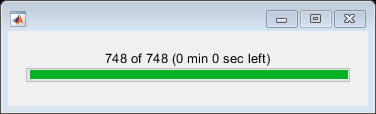

det = Detector(dsname);
det.detections();

detectors = load(folder + "\\detectors\\detectors.mat").D;
detectors = detectors(fileidx);

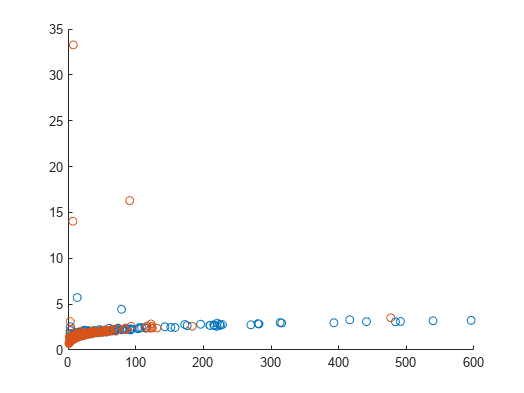

% deltas = arrayfun(@(d) d.mu_n - d.mu_s, [detectors.segmms1white]);
% deltalimwhite = prctile(deltas, 50);
% figure
% histogram(deltas)
% deltas = arrayfun(@(d) d.mu_n - d.mu_s, [detectors.segmms1]);
% deltalim = prctile(deltas, 50);
% figure
% histogram(deltas)
% de = arrayfun(@(d) max(d.probs) - min(d.probs), [detectors.bledwhite]);
% histogram(de)

klsn = arrayfun(@(d) d.KLDiv_sn, [detectors.segmms1white]);
klns = arrayfun(@(d) d.KLDiv_ns, [detectors.segmms1white]);
mds = arrayfun(@(d) d.MDist_s, [detectors.segmms1white]);
mdn = arrayfun(@(d) d.MDist_n, [detectors.segmms1white]);
mdhmin = arrayfun(@(d) d.MDist_minH, [detectors.segmms1white]);
dH = arrayfun(@(d) d.Hmax - d.Hmin, [detectors.segmms1white]);
hassignal = arrayfun(@(d) any(contains(d.annotations.Annotation, "Bm")), detectors);
% b = linspace(0, 500, 20);
% figure
% hold on
% histogram(kl(hassignal), b, "Normalization","probability");
% histogram(kl(~hassignal), b, "Normalization","probability");
% hold off
figure
hold on
scatter(klsn(hassignal), klns(hassignal));
scatter(klsn(~hassignal), klns(~hassignal));
hold off

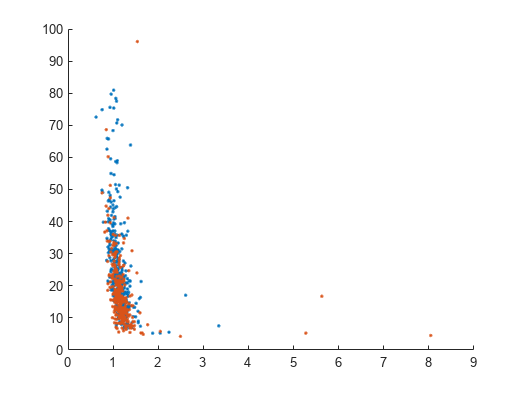


figure
hold on
scatter(mdn(hassignal), mdhmin(hassignal),'.');
scatter(mdn(~hassignal), mdhmin(~hassignal),'.');
hold off

labels = [];
pkmeans = [];
psegmms1white = [];
psegmms1 = [];
psegmmscatwhite = [];
psegmmscat = [];
ebledwhite = [];
ebled = [];
downsample = 1;

%scale the probabilities
scalesegmms1white = max(arrayfun(@(d) d.mu_n - d.mu_s, [detectors.segmms1white]));
scalesegmms1 = max(arrayfun(@(d) d.mu_n - d.mu_s, [detectors.segmms1]));
scalekmeans = max(arrayfun(@(d) d.mu_n - d.mu_s, [detectors.kmeans]));

% scale_z = 2.55;

for i = 1:numel(detectors)
    d = detectors(i);
    kmeans = d.kmeans;
    segmms1white = d.segmms1white;
    segmms1 = d.segmms1;

%     segmmscatwhite = d.segmmscatwhite;
%     segmmscat = d.segmmscat;

    bledwhite = d.bledwhite;
    bled = d.bled;

    if ~all(d.truelabels == 0)   
%         sc = max((segmms1white.MDist_s)/scale_z, 1);
        sc=1;
        psegmms1white = [psegmms1white, segmms1white.probs(1:downsample:end) * segmms1white.converged * sc];
        
%         sc = max((segmms1.MDist_s)/scale_z, 1);
        psegmms1 = [psegmms1, segmms1.probs(1:downsample:end) * segmms1.converged * sc];

%         sc = max((kmeans.mu)/2, 1);
        pkmeans = [pkmeans, kmeans.probs(1:downsample:end) * kmeans.converged];

%         psegmmscatwhite = [psegmmscatwhite, segmmscatwhite.probs(1:downsample:end) * segmmscatwhite.converged];
%         psegmmscat = [psegmmscat, segmmscat.probs(1:downsample:end) * segmmscat.converged];

        ebledwhite = [ebledwhite, bledwhite.probs(1:downsample:end)];
        ebled = [ebled, bled.probs(1:downsample:end)];

        labels = [labels, d.truelabels(1:downsample:end)];
    end
end

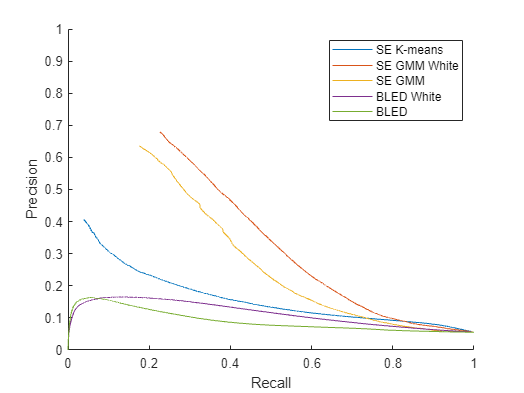


xc = 'reca';
yc = 'prec';
xlims = [0, 1];
ylims = [0, 1];

% idx = labels == 1;

figure
hold on
[x, y] = perfcurve(labels, pkmeans, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
[x, y] = perfcurve(labels, psegmms1white, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
[x, y] = perfcurve(labels, psegmms1, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)

% [x, y] = perfcurve(labels, psegmmscatwhite, 1, 'XCrit',xc, 'YCrit',yc);
% plot(x, y)
% [x, y] = perfcurve(labels, psegmmscat, 1, 'XCrit',xc, 'YCrit',yc);
% plot(x, y)

[x, y] = perfcurve(labels, ebledwhite, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
[x, y] = perfcurve(labels, ebled, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)

hold off
legend("SE K-means", "SE GMM White", "SE GMM", "BLED White", "BLED")
xlabel("Recall")
ylabel("Precision")
xlim(xlims);
ylim(ylims);

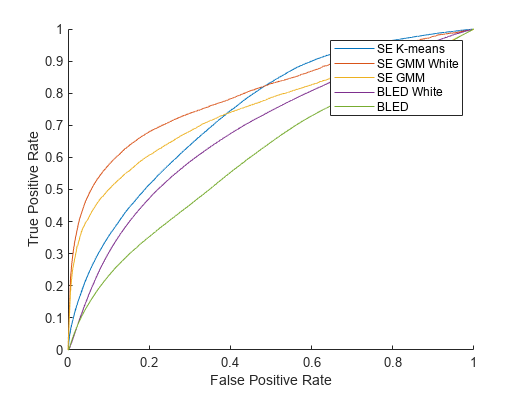


xc = 'fpr';
yc = 'tpr';
xlims = [0, 1];
ylims = [0, 1];

% idx = labels == 1;

figure
hold on
[x, y] = perfcurve(labels, pkmeans, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
[x, y] = perfcurve(labels, psegmms1white, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
[x, y] = perfcurve(labels, psegmms1, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)

% [x, y] = perfcurve(labels, psegmmscatwhite, 1, 'XCrit',xc, 'YCrit',yc);
% plot(x, y)
% [x, y] = perfcurve(labels, psegmmscat, 1, 'XCrit',xc, 'YCrit',yc);
% plot(x, y)

[x, y] = perfcurve(labels, ebledwhite, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
[x, y] = perfcurve(labels, ebled, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)

hold off
legend("SE K-means", "SE GMM White", "SE GMM", "BLED White", "BLED")
xlabel("False Positive Rate")
ylabel("True Positive Rate")
xlim(xlims);
ylim(ylims);

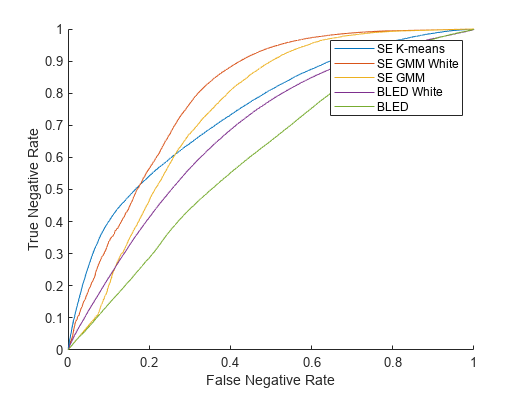


xc = 'fnr';
yc = 'tnr';
xlims = [0, 1];
ylims = [0, 1];

% idx = labels == 1;

figure
hold on
[x, y] = perfcurve(labels, pkmeans, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
[x, y] = perfcurve(labels, psegmms1white, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
[x, y] = perfcurve(labels, psegmms1, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
[x, y] = perfcurve(labels, ebledwhite, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
[x, y] = perfcurve(labels, ebled, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
hold off
legend("SE K-means", "SE GMM White", "SE GMM", "BLED White", "BLED")
xlabel("False Negative Rate")
ylabel("True Negative Rate")
xlim(xlims);
ylim(ylims)

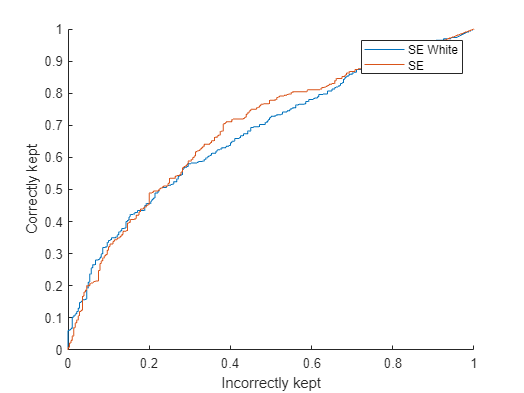

discardwhite = arrayfun(@(d) (d.Hmax - d.Hmin)*d.converged, [detectors.segmms1white]);
discard = arrayfun(@(d) (d.MDist_s)*d.converged, [detectors.segmms1]);
truediscard = cellfun(@(y) any(y), {detectors.truelabels});

xc = 'fpr';
yc = 'tpr';

figure
hold on
[x, y, t] = perfcurve(truediscard, discardwhite, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
[x, y] = perfcurve(truediscard, discard, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)
hold off
legend("SE White", "SE")
xlabel("Incorrectly kept")
ylabel("Correctly kept")

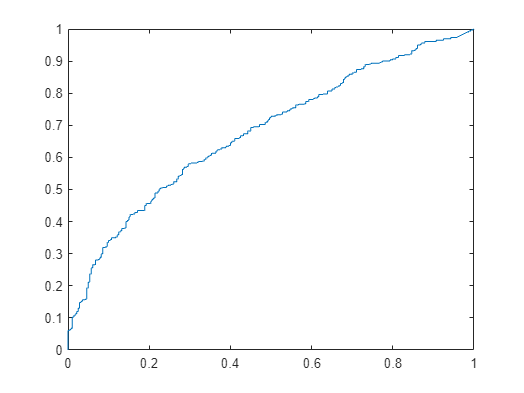


[x, y, t] = perfcurve(truediscard, discardwhite, 1, 'XCrit',xc, 'YCrit',yc);
plot(x, y)

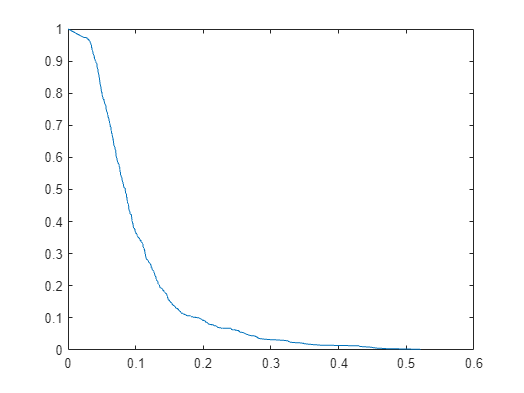


plot(t, y)

hassignal = cellfun(@(y) any(y), {detectors.truelabels});
names = ["kmeans", "segmms1white", "segmms1", "bledwhite", "bled"];
%get the stats of non-converged files that contain signal
for name = names(1:3)
    name
    conv = arrayfun(@(r) r.(name).converged, detectors);
    notconvsignal = hassignal & ~conv;
    numnotconv = sum(notconvsignal)
    pnotconv = sum(notconvsignal)/sum(hassignal)
    nummissedcalls = sum(arrayfun(@(r) size(r.annotations, 1), detectors(notconvsignal)))
    totalcalls = sum(arrayfun(@(r) size(r.annotations, 1), detectors))
    pmissedcalls = nummissedcalls/totalcalls
end

name = "kmeans"

numnotconv = 0

pnotconv = 0

nummissedcalls = 0

totalcalls = 3393

pmissedcalls = 0

name = "segmms1white"

numnotconv = 12

pnotconv = 0.0261

nummissedcalls = 43

totalcalls = 3393

pmissedcalls = 0.0127

name = "segmms1"

numnotconv = 41

pnotconv = 0.0891

nummissedcalls = 196

totalcalls = 3393

pmissedcalls = 0.0578


rocdetectors = detectors;%(hassignal);
thresh.segmms1white = linspace(0,1, 10);
thresh.segmms1 = thresh.segmms1white;
thresh.kmeans = [linspace(0,0.9,10), 0.95, 0.99, 0.991, 0.999,1];
thresh.bledwhite = linspace(1,10, 40);
thresh.bled = linspace(1,10, 20);

for name = names(1:4)
    name
    det = [rocdetectors.(name)];    
    probs = {det.probs};
    delta = arrayfun(@(d) d.mu_n - d.mu_s, det);  
    dH = arrayfun(@(d) d.Hmax - d.Hmin, det);
    
    if name == "segmms1" || name == "segmms1white"
        mdh = arrayfun(@(d) d.MDist_minH, det);
        mds = arrayfun(@(d) d.MDist_s, det);
        sc = min(dH / 0.25, 1);
        sc = dH > snr2dh(db2mag(-100), sizef);
        conv = arrayfun(@(d) d.converged, det);
        probs = arrayfun(@(i) probs{i} * conv(i), 1:numel(probs), 'UniformOutput',false);
    end
    anns = {rocdetectors.annotations};
    labels = {rocdetectors.truelabels};
    numdet.(name) = zeros(size(thresh));
    numnoisesamples.(name) = zeros(size(thresh));
    for k = 1:numel(thresh.(name))
        r = thresh.(name)(k)
        mask = cellfun(@(p) p > r, probs, 'UniformOutput',false);
        idx = 1:numel(mask);
        ndet = sum(arrayfun(@(i) numdetections(mask{i}, anns{i}), idx));
        nnoise = sum(arrayfun(@(i) noisesamplesdet(mask{i}, labels{i}), idx));
        numdet.(name)(k) = ndet;
        numnoisesamples.(name)(k) = nnoise;
    end
end

name = "kmeans"

r = 0

nann = sum(arrayfun(@(r) sum(contains(r.annotations.Annotation, "Bm")), rocdetectors));
nnoise = sum(arrayfun(@(r) sum(~r.truelabels), rocdetectors));

tnoise = 0.05;
thresh05 = interp1(numnoisesamples.segmms1white/nnoise, thresh.segmms1white, 0.05)
interp1(thresh.segmms1white, numdet.segmms1white/nann, thresh05)

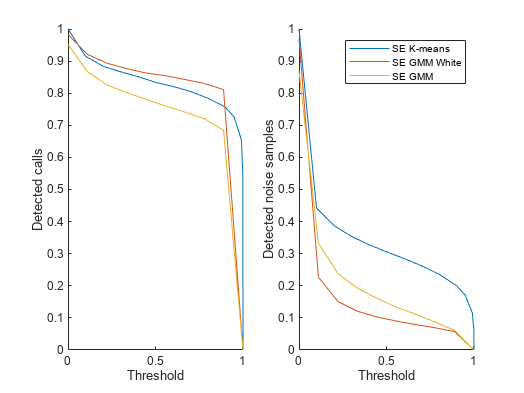


% figure
% hold on
figure
hold on
for name = names(1:4)
    tpr = numdet.(name)/nann;
    pnoise = numnoisesamples.(name)/nnoise;    
    subplot(1, 2, 1)
    hold on
    plot(thresh.(name), tpr)
    xlabel("Threshold")
    ylabel("Detected calls")
    subplot(1, 2, 2)
    hold on
    plot(thresh.(name), pnoise)
    xlabel("Threshold")
    ylabel("Detected noise samples")    
end
hold off
legend("SE K-means", "SE GMM White", "SE GMM")

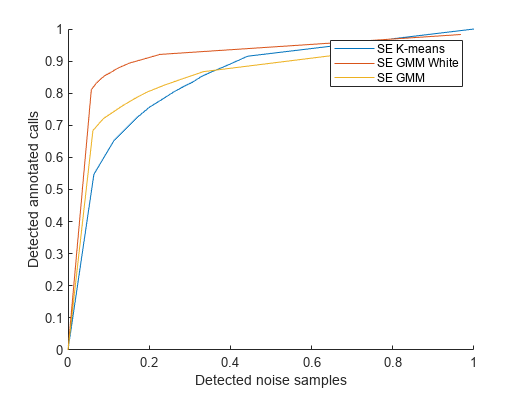


figure
hold on
for name = names(1:3)
    tpr = numdet.(name)/nann;
    pnoise = numnoisesamples.(name)/nnoise;
    plot(pnoise, tpr)
end
hold off
legend("SE K-means", "SE GMM White", "SE GMM")
ylabel("Detected annotated calls")
xlabel("Detected noise samples")

w = load(folder + "\\noise\\NoiseEstimate.mat").noiseEstimates;
dl = DataLoader2(folder, 'wav', 'single', true);
info = dl.filelist;

wn = w./fb.lambdas';
wn = wn(:, fileidx);
wnlog = 10*log10(wn);
wnnorm = max(wnlog, [], 'all');
wnlog  = wnlog - wnnorm;
wnlogg = imgaussfilt(wnlog, [0.01, 1.5])

wnlogg = 48×2590 single matrix
  -15.9107  -16.0012  -16.0180  -15.9742  -15.9515  -16.0299  -16.1366  -16.1984  -16.2568  -16.3146  -16.2937  -15.9387  -14.9885  -13.4015  -11.6452  -10.3605   -9.7532   -9.5723   -9.5439   -9.4906   -9.4263   -9.3901   -9.4192   -9.5246   -9.6261   -9.7200   -9.8197   -9.9736  -10.1556  -10.3211  -10.4182  -10.4676  -10.4899  -10.5346  -10.5845  -10.5972  -10.5584  -10.5035  -10.4694  -10.3831  -10.1318   -9.7307   -9.3472   -9.1418   -9.1267   -9.1972   -9.2592   -9.2529   -9.1850   -9.1177
  -16.1121  -16.2675  -16.3414  -16.3210  -16.2772  -16.3260  -16.4427  -16.5555  -16.6526  -16.7115  -16.6727  -16.3250  -15.4065  -13.8348  -12.0627  -10.7577  -10.1317   -9.9379   -9.9051   -9.8521   -9.7980   -9.7845   -9.8302   -9.9179   -9.9866  -10.0495  -10.1396  -10.3160  -10.5472  -10.7737  -10.9246  -10.9994  -11.0031  -10.9876  -10.9831  -10.9754  -10.9394  -10.8997  -10.8717  -10.7963  -10.5721  -10.2030   -9.8261   -9.5920   -9.5246   -9.5494   -9.60

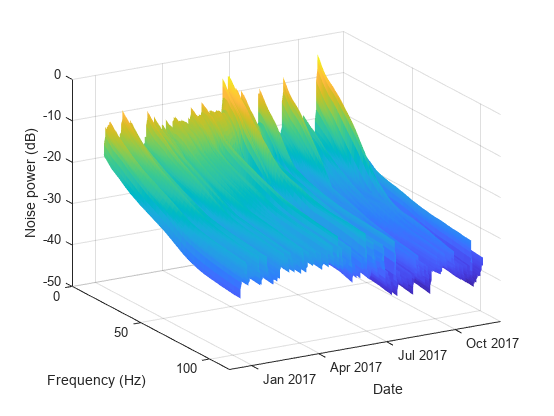

f = fb.fc;
t = [info.time];
t = t(fileidx);
figure
surf(t, f, wnlogg, 'EdgeColor','none')
set(gca, 'YDir', 'reverse')
xlabel("Date")
ylabel("Frequency (Hz)")
zlabel("Noise power (dB)")
view([-30 25])

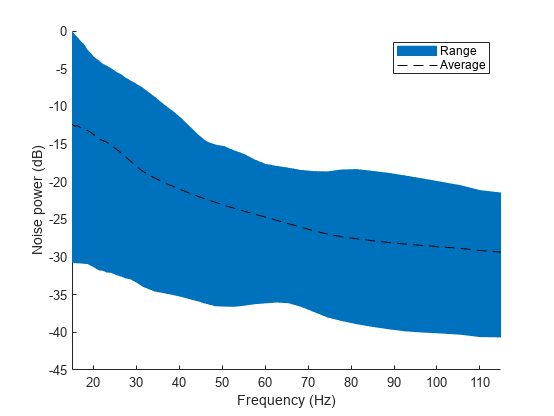

figure
wnmax = max(wnlog, [], 2);
wnmin = min(wnlog, [], 2);
wnmean = 10*log10(mean(wn, 2)) - wnnorm;
wfill = [wnmax; flipud(wnmin)];
ffill = [f, fliplr(f)];
wntot = sum(wn, 1);
wntot = 10*log10(wntot./max(wntot));
figure
hold on
fill(ffill, wfill, [0 0.4470 0.7410], 'EdgeColor','none')
plot(f,wnmean, 'k--')
hold off
xlabel("Frequency (Hz)")
ylabel("Noise power (dB)")
legend("Range", "Average")
xlim([min(f), max(f)])



nann = cellfun(@(a) size(a, 1), anns);
dt = [duration(2, 0, 0), diff(t)];
startidx = find(dt > duration(1,0,0))

startidx =      1    15    29    43    57    71    85    99   113   127   141   155   169   183   197   211   225   239   253   267   281   295   309   323   337   351   365   379   393   407   421   435   449   463   477   491   505   519   533   547   561   575   589   603   617   631   645   659   673   687


endidx = [startidx(2:end)+1, numel(t)]

endidx =     16    30    44    58    72    86   100   114   128   142   156   170   184   198   212   226   240   254   268   282   296   310   324   338   352   366   380   394   408   422   436   450   464   478   492   506   520   534   548   562   576   590   604   618   632   646   660   674   688   702


nann = arrayfun(@(i) sum(nann(startidx(i):endidx(i))), 1:numel(startidx))

nann =     68    16     7     0     4    12    10     1     1     2     0     2    11     0     1     7    13     1     7     6     0     3    19    38    57    37    26    29    19    41    18     1     2    14    39    19    25    92    20    18    36    64    38    61    16    31    90    17    76    62


wntotavg = arrayfun(@(i) mean(wntot(startidx(i):endidx(i))), 1:numel(startidx))

wntotavg = 1×185 single row vector
  -13.5016   -7.9966   -8.6030   -7.3234   -6.7883   -7.8109  -11.3912   -9.7682  -11.0146   -9.5283  -12.6166  -11.2938  -10.0600   -8.5916   -6.5229  -14.4008  -12.5183  -11.9592  -12.6511   -8.4864   -8.2164  -13.0701  -14.0559  -14.5362  -15.1773  -15.9371  -14.0441  -14.6754  -15.1255  -14.6879  -13.8849  -11.0337  -10.0518   -6.6664  -11.1089   -8.8201   -9.3776  -12.5901   -7.6161  -11.1378  -12.0572  -12.2469  -12.8650  -11.1457   -9.5090  -10.2450  -12.8341   -8.9631  -11.7128  -11.7913


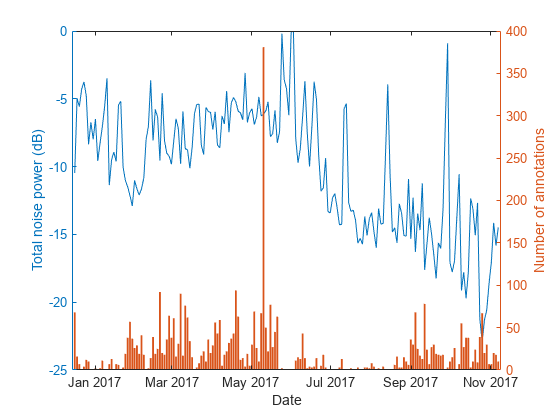

figure
yyaxis left
plot(t(startidx), wntotavg - max(wntotavg))
xlabel("Date")
ylabel("Total noise power (dB)")
yyaxis right
bar(t(startidx), nann)
xlabel("Date")
ylabel("Number of annotations")

function num = numdetections(mask, annotations)
    num = 0;
    for i = 1:size(annotations, 1)
        a = annotations(i, :);
        if any(mask(a.ScatteringStartIndex : min(a.ScatteringEndIndex, numel(mask)))) && contains(a.Annotation, "Bm")
            num  = num + 1;
        end
    end
end

function num = nummisses(mask, annotations)
    num = 0;
    for i = 1:size(annotations, 1)
        a = annotations(i, :);
        if ~any(mask(a.SpectrogramStartIndex : a.SpectrogramEndIndex))
            num  = num + 1;
        end
    end
end

function num = noisesamplesdet(mask, truelabels)    
%     falserle = Tools.rle(~truelabels);
%     num = 0;
%     for i = 1:size(falserle, 1)
%         a = falserle(i, :);
%         if any(mask(a.Start : a.End-1))
%             num  = num + 1;
%         end
%     end
      mask = mask & (~truelabels);
      num = sum(mask);
end